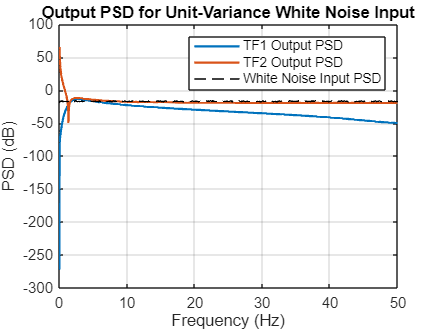

clc; clear; close all;

%% First TF
num1 = [0.02679  -0.05951  0.01895  0.03348  -0.01971];
den1 = [1  -3.952  5.857  -3.857  0.9523];
Ts1 = 0.01;
Hd1 = tf(num1, den1, Ts1);

%% Second TF
num2 = [0.1056  -0.4356  0.6599  -0.4356  0.1056];
den2 = [1  -4.022  6.044  -4.022  1];
Ts2 = 0.01;
Hd2 = tf(num2, den2, Ts2);

%% Frequency response (magnitude squared = PSD for white noise input)
nfft = 2048;
[H1, w] = freqz(num1, den1, nfft, 1/Ts1);  % w in Hz
H2 = freqz(num2, den2, nfft, 1/Ts2);

PSD1 = abs(H1).^2;   % output PSD
PSD2 = abs(H2).^2;

%% Generate white noise and compute its PSD
N = 100000; % number of samples
white_noise = randn(N,1); % unit variance white noise

[PSD_white, f_white] = pwelch(white_noise, hamming(1024), 512, nfft, 1/Ts1);

%% Plot all three
figure;
plot(w, 10*log10(PSD1), 'LineWidth', 1.5); hold on;
plot(w, 10*log10(PSD2), 'LineWidth', 1.5);
plot(f_white, 10*log10(PSD_white), 'k--', 'LineWidth', 1);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD (dB)');
title('Output PSD for Unit-Variance White Noise Input');
legend('TF1 Output PSD', 'TF2 Output PSD', 'White Noise Input PSD');

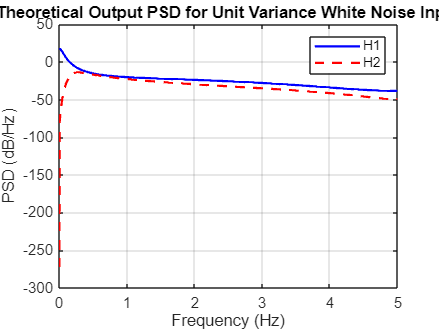




%% Define transfer functions
num1 = [0.413 0.1762 -1.402 0.1762 0.413];
den1 = [1 19.38 -40.79 19.38 1];

num2 = [0.02679 -0.05951 0.01895 0.03348 -0.01971];
den2 = [1 -3.952 5.857 -3.857 0.9523];

Ts = 0.1; % sample time

%% Frequency vector for plotting
nfft = 1024;
[H1_w, w] = freqz(num1, den1, nfft, 1/Ts);
[H2_w, ~]  = freqz(num2, den2, nfft, 1/Ts);

%% For white noise input with unit variance:
PSD1 = abs(H1_w).^2; % output PSD
PSD2 = abs(H2_w).^2;

%% Plot theoretical PSDs for H1 and H2
figure;
plot(w, 10*log10(PSD1), 'b', 'LineWidth', 1.5); hold on;
plot(w, 10*log10(PSD2), 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('H1', 'H2');
title('Theoretical Output PSD for Unit Variance White Noise Input');


%% Generate and display white noise
N = 2000;          % number of samples
rng(1);            % reproducible random numbers
white_noise = randn(N,1); % mean 0, variance 1

% Check variance
fprintf('White noise variance: %.4f\n', var(white_noise));

White noise variance: 1.0540


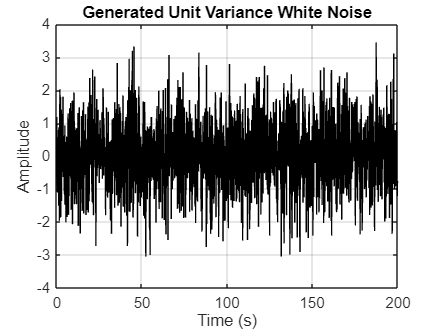


%% Plot white noise in time domain
figure;
plot((0:N-1)*Ts, white_noise, 'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('Generated Unit Variance White Noise');
grid on;

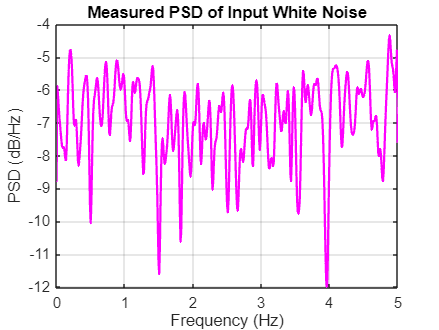


%% Plot PSD of the generated white noise
[PSD_in, f_in] = pwelch(white_noise, hamming(256), 128, 1024, 1/Ts);

figure;
plot(f_in, 10*log10(PSD_in), 'm', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
title('Measured PSD of Input White Noise');
grid on;